# processing data

fileEnergy = readtable('result_fileEnergy.csv');
fileCAAT = readtable('result_fileCAAT.csv');

filePAC = readtable('result_filePAC.csv');

fileEnergy = sortrows(fileEnergy, {'Timer_Row'});
fileCAAT = sortrows(fileCAAT, {'Timer_Row'});
filePAC = sortrows(filePAC, {'Timer_Row'});

fileEnergyX = fileEnergy{:, 'Timer_Row'};
fileEnergyX = fileEnergyX';

## Energy consumption

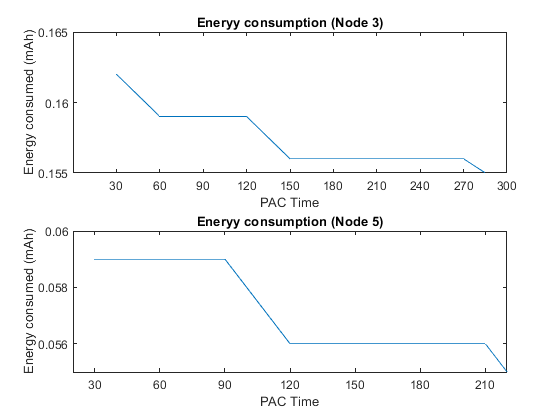

figure;
PAC_time_label = 'PAC Time';

fileEnergyY3 = fileEnergy{:,'Node3'};
fileEnergyY3 = fileEnergyY3';
%plot(aa, bb)
subplot(2,1,1), plot(fileEnergyX, fileEnergyY3)
title('Eneryy consumption (Node 3)')  
ylim([0.155 0.165])
xticks(30:30:300)
xlabel(PAC_time_label) 
ylabel('Energy consumed (mAh)') 

fileEnergyY5 = fileEnergy{:,'Node5'};
fileEnergyY5 = fileEnergyY5';
subplot(2,1,2), plot(fileEnergyX, fileEnergyY5)
title('Eneryy consumption (Node 5)') 
ylim([0.055 0.06])
xticks(30:30:300)
xlabel(PAC_time_label) 
ylabel('Energy consumed (mAh)') 

%ylim([0.15 0.165])
%xlim([30 320])

saveas(gcf,'Energy.png')

## Number of Address Changes in 3600s

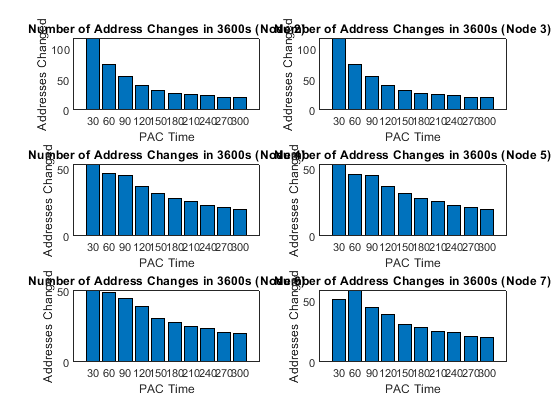

for i = 2:7
    
    subplot(3,2,i-1)
    
    PAC_freq = filePAC{:,strcat('Node',int2str(i))}';
    bar(30:30:300,PAC_freq)
    str = sprintf('Number of Address Changes in 3600s (Node %d)', i);
    title(str)
    xlabel(PAC_time_label) 
    ylabel('Addresses Changed')
end

saveas(gcf,'AddressChanges.png')

## Number of Failed Address Changes in 3600s

the formular is 

address_failed = max_PAC_signal - num_SuccessfulAddrChanged

max_addressChangeSignal is gotten from node 1

num_SuccessfulAddrChanged is the number of times the node successfully changed address for 3600s for a certain timer

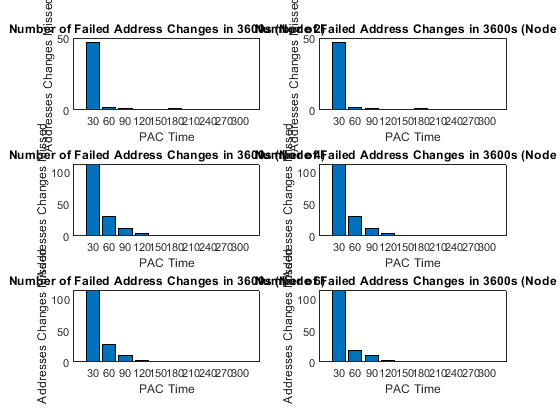

for i = 2:7
    subplot(3,2,i-1)
    PAC_freq = filePAC{:,strcat('Node',int2str(i))}';
    
    PAC_freq_loss = filePAC{:,'Node1'}' - PAC_freq;
    bar(30:30:300,PAC_freq_loss)
    str = sprintf('Number of Failed Address Changes in 3600s (Node %d)', i);
    title(str) 
    xlabel(PAC_time_label) 
    ylabel('Addresses Changes Missed')
end

saveas(gcf,'AddressesChangesMissed.png')

## Computing ADW

The formula is 

ADW = caat - TTL

where caat is given by

caat = PAC_signal - addr_change_time

PAC signal is the time Node 1 sent address change signal

addr_change_time is the time the node successfully changed address

TTL is time to live. It is the maximum time a packet is expected to still be on transit in the network.

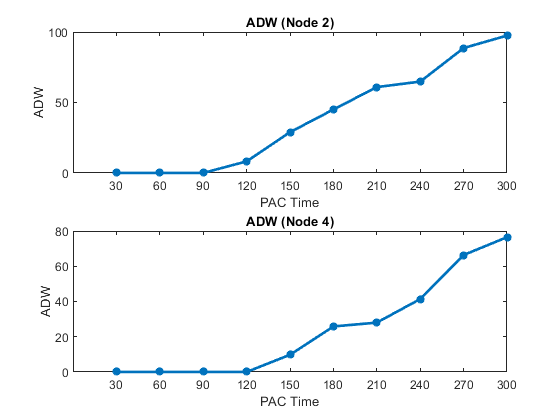

caat = fileCAAT{:, :};
caat = caat(:, 2:end);

adw = caat - 64;
adw = max(adw, 0);

figure;
data = adw(:,2);
subplot(2,1,1), plot(30:30:300, data, '-*', 'LineWidth',2)
title('ADW (Node 2)') 
xticks(30:30:300)
xlabel(PAC_time_label) 
ylabel('ADW')

data = adw(:,4);
subplot(2,1,2), plot(30:30:300, data, '-*', 'LineWidth',2)
title('ADW (Node 4)') 
xticks(30:30:300)
xlabel(PAC_time_label) 
ylabel('ADW')